% a04_p2_scatter_plot_model_fits_v5.mlx

clear all; close all; clc;

% load model comparison/fitting results
load('mc_results_v5_n10.mat')

% set data path
currentDir = pwd;
exptDir = currentDir(1:regexp(pwd,'03expCode')-1);
outDir = [exptDir '02figures/fig3_model_comparison'];
addpath(genpath([exptDir '03expCode/01pretest/data']));
addpath(genpath([exptDir '03expCode/04posttest/data']));
addpath(genpath([currentDir 'model_comparison_function']))

% define subjects and sessions
sub_slc = [1:4,6:10]; % excluded sub5
n_sub = numel(sub_slc);
n_all_sub = sub_slc(end);
all_sess = 1:9;
n_sess = numel(all_sess);

## delta-AIC plot

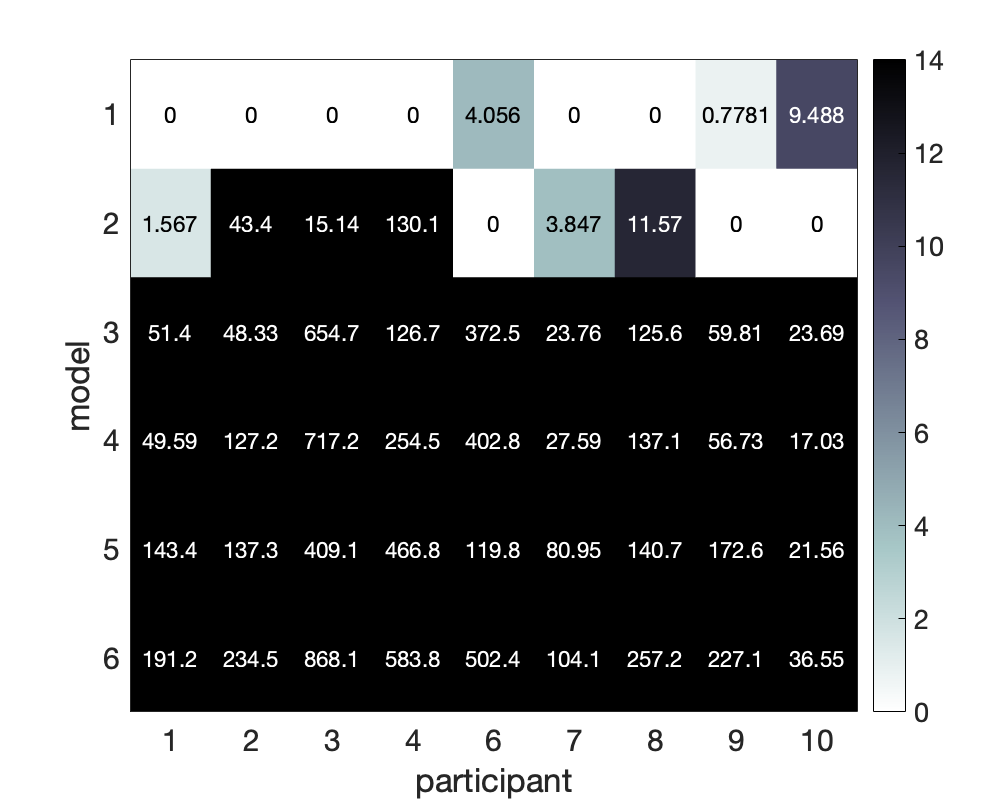

deltaAIC = AIC - min(AIC, [], 2);
% exclude subjects
deltaAIC_ = deltaAIC(sub_slc,:)';

figure
set(gca, 'LineWidth', 2, 'FontSize', 15)
set(gcf, 'Position',[10 10 500 400])
heatmap(deltaAIC_, ...
    'XLabel','participant', 'YLabel', 'model',...
    'XData',sub_slc,...
    'Colormap', flipud(bone),...
    'ColorLimits', [0, 14], 'ColorbarVisible', 'off', 'GridVisible', 'off','FontSize', 15);
colorbar

% % add the bar plot
% subplot(2,5,[5,10])
% win_count = sum(deltaAIC_==0, 2);
% barh(win_count)

% save figure
fignm = 'fig3_delta_AIC';
saveas(gca, fullfile(outDir, fignm), 'epsc')

## extract fits for scatter plots


% define x-grid to be eval
ms_unique = deal([-500, -300:50:300, 500]);

% define PMF
P_Afirst                      = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig);
P_Vfirst                      = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig));
P_simultaneous                = @(SOA, mu, sig, c, lambda) ...
    1 - (lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig)) ...
    - (lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig)));

% define model
M1 = {@(p) P_Vfirst(ms_unique, p(1), p(3), p(5), p(7));...
    @(p) P_simultaneous(ms_unique, p(1), p(3), p(5), p(7));...
    @(p) P_Afirst(ms_unique, p(1), p(3), p(5), p(7));...
    @(p) P_Vfirst(ms_unique, p(2), p(4), p(6), p(8));...
    @(p) P_simultaneous(ms_unique, p(2), p(4), p(6), p(8));...
    @(p) P_Afirst(ms_unique, p(2), p(4), p(6), p(8))};

% pre-allocate, each cell has the size (number of all subjects x number of
% sessions), within each cell is a matrix of number of response conditions
% (1:3: pre, 4:6: post) x percentage of responses in each condition (15 levels).
% Note that pResp_data and pResp_fit has different order of conditions
[pResp_data, pResp_M1_fit, pResp_M7_fit] = deal(cell(n_all_sub, n_sess));

for sub = sub_slc

    for s = all_sess % loop by session, but plot by adaptor SOA

        %%%%%%%%%%%% 1) p(a-first), p(v-first) from raw data

        %%%%% pre-test
        load(['pretest_sub' num2str(sub) '_session' num2str(s) '.mat'])
        pre_s_unique                               = ExpInfo.SOA; % unique SOA levels, in s
        ms_unique                                  = pre_s_unique * 1e3; % unique SOA levels, in ms
        pre_numTrials                              = ExpInfo.nTrials; % num of trials per SOA
        % inititate
        pre_r_org                                  = NaN(length(pre_s_unique), pre_numTrials);
        pre_respCount                              = NaN(3, length(pre_s_unique));
        for i                                      = 1:length(pre_s_unique)
            iSOA                                       = pre_s_unique(i);
            iResp                                      = Response.order(ExpInfo.trialSOA == iSOA);
            pre_r_org(i,:)                             = iResp; % this matrix has a size of length(s_unique) x numTrials
            for j                                      = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
                pre_respCount(j,i)                         = sum(iResp == j);
            end
        end

        %%%%% post-test
        % load data and define key parameters
        load(['posttest_sub' num2str(sub) '_session' num2str(s) '.mat'])
        post_s_unique                              = ExpInfo.SOA; % unique SOA levels, in ms
        ms_unique                             = post_s_unique * 1e3; % unique SOA levels, in s
        post_numTrials                             = ExpInfo.nTrials; % num of trials per SOA
        % inititate
        post_r_org                                 = NaN(length(post_s_unique), post_numTrials);
        post_respCount                             = NaN(3, length(post_s_unique));
        for i                                      = 1:length(post_s_unique)
            iSOA                                       = post_s_unique(i);
            iResp                                      = Response.order(ExpInfo.trialSOA == iSOA);
            post_r_org(i,:)                            = iResp; % this matrix has a size of length(s_unique) x numTrials
            for j                                      = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
                post_respCount(j,i)                        = sum(iResp == j);
            end
        end

        % matrix on the right: each row is the percentage of response at
        % each SOA level, where row indicates:
        % 1 = pre-V, 2 = pre-simul, 3 = pre-A,
        % 4 = post-V, 5 = post-simul, 6 = post-A
        pResp_data{sub, s}                   = [pre_respCount/pre_numTrials; post_respCount/post_numTrials];

        %%%%%%%%%%%% 2)p(a-first_M1_fit), p(v-first_M1_fit) from the
        % fitting of the full model (M1);

        % extract M1 best-fitting parameters
        M1_para = estP{sub}{s, 1};

        % matrix on the right: each row is the percentage of response at
        % each SOA level, where row indicates:
        % 1 = pre-V, 2 = pre-simul, 3 = pre-A,
        % 4 = post-V, 5 = post-simul, 6 = post-A
        pResp_M1_fit{sub, s} = arrayfun(@(c) M1{c}(M1_para), 1:6, 'UniformOutput', false);
    end
end

## scatter plot of all subjects for M1, pre/post x 6 response condition, color code = test SOA


% set plotting parameters
n_test_soa = numel(ms_unique);
% color code: test SOA (15 levels)
cmap = parula;
cidx = floor(linspace(1,230,n_test_soa));
% marker: subject
markers = ['o','s','d','^','v','>','<','p','*','h'];
condTitle = {'p_{pre}("vision lead")', 'p_{pre}("simultaneous")', 'p_{pre}("audition lead")',...
    'p_{post}("vision lead")', 'p_{post}("simultaneous")','p_{post}("audition lead")'};
labels = split(sprintf('%d ',ms_unique),' ');

% initiate figure
figure; hold on
set(gcf,'position',[0 0 800 500]);

for sub = sub_slc
    for c = 1:6
        subplot(2,3,c); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
        line; axis square
        title(condTitle{c})
        xlabel('data'); ylabel('model fit');

        for s = 1:n_sess

            for t = 1:n_test_soa
                i_v_first_data = pResp_data{sub, s}(c,t);
                i_v_first_M1_fit = pResp_M1_fit{sub, s}{c}(t);
                %                 l1(t) = scatter(i_v_first_data, i_v_first_M1_fit, 50, markers(sub),'MarkerFaceColor',cmap(cidx(t),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5);
                scatter(i_v_first_data, i_v_first_M1_fit, 50, markers(sub),'MarkerFaceColor',cmap(cidx(t),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5);
            end
        end

    end
end

% save figure
fignm = 'fig3_model_fit';
saveas(gca, fullfile(outDir, fignm), 'epsc')


## plot legend by hand

figure; hold on
ylim([-1, 16])
for t = 1:n_test_soa
    scatter(1,t,70,'o','filled','MarkerFaceColor',cmap(cidx(t),:), 'MarkerEdgeColor','none');
    text(1.1, t, num2str(ms_unique(t)))
end
fignm = 'fig3_model_fit_legend';
saveas(gca, fullfile(outDir, fignm), 'epsc')


## scatter plot of all subjects for M1, pre/post x 6 response condition, color code = adaptor SOA

%
% % color code: adaptor SOA (9 levels)
% load('RandomAdaptorOrder.mat' );
% cmap = parula;
% cidx = floor(linspace(1,230, n_sess));
% % marker: subject
% markers = ['o','s','d','^','v','>','<','p','*','h'];
% condTitle = {'pre-test, p(V-first)','pre-test, p(simul)','pre-test, p(A-first)',...
%     'post-test, p(V-first)','post-test, p(simul)','post-test, p(A-first)'};
% labels = split(sprintf('%d ',ms_unique),' ');
%
% % initiate figure
% figure; hold on
% set(gcf,'position',[0 0 700 500]);
%
% for sub = all_sub
%
%     % sort by adaptor soa
%     i_adaptor_soa = randomAdaptorOrder(sub,:);
%     [sorted_adaptor_soa, order] = sort(i_adaptor_soa);
%
%     for c = 1:6
%         subplot(2,3,c); set(gca, 'LineWidth', 1, 'FontSize', 15); hold on
%         line; axis square
%         title(condTitle{c})
%         xlabel('data'); ylabel('model fit');
%
%         for s = order
%
%             for t = 1:n_test_soa
%                 i_v_first_data = pResp_data{sub, s}(c,t);
%                 i_v_first_M1_fit = pResp_M1_fit{sub, s}{c}(t);
%                 l2(s) = scatter(i_v_first_data, i_v_first_M1_fit, 50, markers(sub),'MarkerFaceColor',cmap(cidx(s),:), 'MarkerEdgeColor','none','MarkerFaceAlpha', 0.5);
%             end
%         end
%
%     end
% end
%
% legend(l2)
% sgtitle('colorcode: adaptor SOA')
